# Laboratorium 4

# Analiza harmoniczna - część 2

Karolina Piotrowska

Zadanie 1

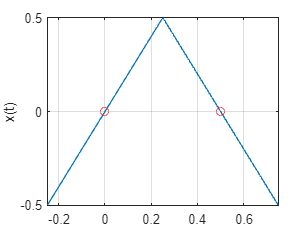

syms t t1 t2 offset x

T0 = 1.0;
t1 = -0.5;
t2 = t1 + T0;

offset = T0/4;

f0 = 1/T0;

w0 = 2*pi*f0;

BND = [t1,t2] + offset;

x = triangularPulse(t1, 0.0, t2, t-offset) - 0.5;

figure
fplot(x, BND), grid on, ylabel('x(t)')
hold on
plot(0, 0, 'ro') %punkty zmiany znaku sygnału
plot(0.5, 0, 'ro')
hold off

Zadanie 2

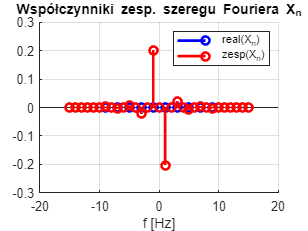

NT = 15;

X=[];

ind = -NT:NT;

for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end

figure
hold on
stem(ind*f0, real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0, imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','zesp(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')

Zadanie 3

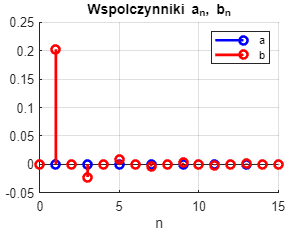

NT = 0:15;
a=[];
b=[];

for n = NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure; 
grid on
hold on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
legend('a','b'),
title('Wspolczynniki a_n, b_n')
hold off

Zadanie 4

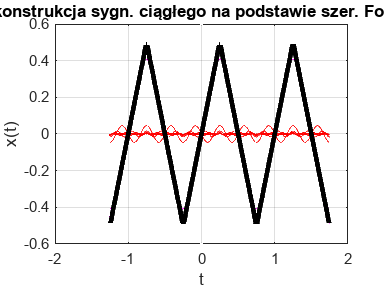

step = (BND(2)-BND(1))/1000;

tt = [BND(1)-T0 : step : BND(2) + T0];

xx = zeros(1,length(tt));
xx = xx + a(1);

figure;
plot(tt,xx,'m')
grid on 
hold on
plot([0, 0],[-0.6, 0.6], 'w.'),
xlabel('t'); ylabel('x(t)');
pause(0.5)

for n = NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    title(sprintf('n = %d',n+1));
    pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygn. ciągłego na podstawie szer. Fouriera')
hold off

Zadanie 5

tt = linspace(BND(1)-T0,BND(2)-T0,3000);
xx = zeros(1,length(tt));
NT = 15

NT = 15

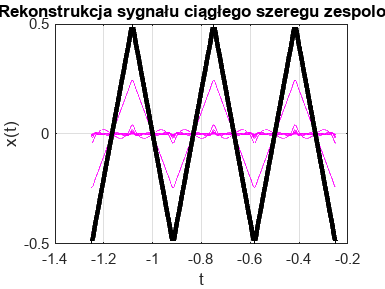

figure;
plot(tt,xx,'m');  
grid on;
hold on;
pause(0.5)
xlabel('t'); 
ylabel('x(t)');
 
for n=-NT:NT
    xx_n=X(NT+1+n)*exp((-1)*1j*6*pi*f0*n*tt);
    xx = xx + real(xx_n);
    plot(tt,xx,'m');
    plot([tt(1),tt(2)],[max(xx)-0.1, min(xx)+0.1],'w.')
end
 
plot(tt,xx,'k','LineWidth',3); 
grid on;
hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('5. Rekonstrukcja sygnału ciągłego szeregu zespolonego')
hold off


syms serr
serr = int(x.^2,t,BND)/T0;
Xabs = abs(X).^2

Xabs =     0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0001         0    0.0005         0    0.0411         0    0.0411         0    0.0005         0    0.0001         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000


Xerr = sum(Xabs)

Xerr = 0.0833

blad = double(abs(serr - Xerr))

blad = 3.3160e-06

Zadanie 6

syms ev
ev = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi))

$$ev = \frac{\sqrt{2}}{2}$$

ev_d = double(ev)

ev_d = 0.7071


ev = sqrt(int(x^2,t,BND)/T0)

$$ev = \frac{\sqrt{3}}{6}$$


ev_r = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

ev_r = 0.2888

Zadanie 7

s = 0;
for i = 2:NT
    s = s + (abs(X(NT+i+1)).^2)/2
end

s = 0

s = 2.5348e-04

s = 2.5348e-04

s = 2.8633e-04

s = 2.8633e-04

s = 2.9488e-04

s = 2.9488e-04

s = 2.9801e-04

s = 2.9801e-04

s = 2.9942e-04

s = 2.9942e-04

s = 3.0013e-04

s = 3.0013e-04

s = 3.0054e-04

thd = sqrt(s)/(abs(X(NT+2))/sqrt(2))

thd = 0.1210

## Zadanie domowe

### Sinusoda modyfikowana

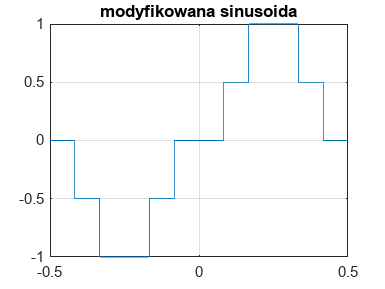

syms t t1 t2 offset x
T0 = 1;
f0 = 1/T0;
w0 = 2*pi*f0;
t1 = -T0/2;
t2 = t1 + T0;
offset = 0;
BND = [t1,t2] + offset;
x = 0.5*(-rectangularPulse(-0.5+1/12, -1/12, t) ...
    - rectangularPulse(-0.5+1/6,-1/6, t) ...
    + rectangularPulse(1/12, 0.5-T0/12, t) ...
    + rectangularPulse(1/6,0.5-1/6, t));
fplot(x, BND)
grid on
title('modyfikowana sinusoida')

Wyznaczanie zespolonych współczynników szeregu Fouriera

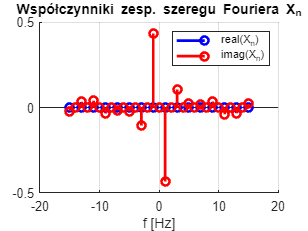

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
 Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
 X(n+NT+1)=Xn;
end
figure; hold on
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

Wyznaczanie współczynników an, bn

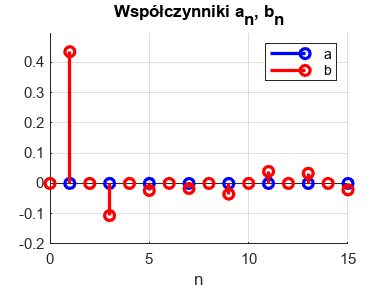

a=[];
b=[];
for n = 0:NT
 a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
 b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end
figure; hold on, grid on
stem(0:NT,a,'b','LineWidth',2);
xlabel('n')
stem(0:NT,b,'r','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

   Rekonstrukcja sygnału ciągłego na podstawie szeregu Fouriera

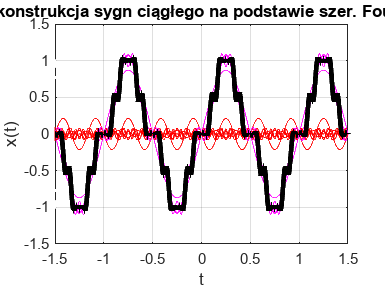

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);
figure;
plot(tt,xx,'m'); grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=1:NT
 xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
 xx = xx + xx_n;
 plot(tt,xx_n,'r');
 plot(tt,xx,'m');
 plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
 title(sprintf('n = %d',n+1));
 pause(0.5)
end
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

Rekonstrukcja sygnału

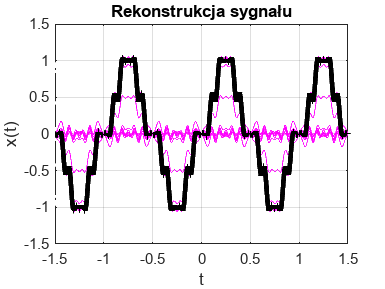

xx = zeros(1,length(tt));
figure(5);
plot(tt,xx,'m'); grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=-NT:NT
 xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
 xx = xx + xx_n;
 pause(0.5);
 plot(tt,real(xx),'m');
 plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end
plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off

Błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = \frac{5}{12}$$

pars_series = sum(abs(X).^2)

pars_series = 0.4111

err_abs = double(abs(pars_wave - pars_series))

err_abs = 0.0056

err_rel = double(err_abs / pars_wave) * 100

err_rel = 1.3464

SKD

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

Wartość skuteczna

skut1 = sqrt(int(x^2,t,BND)/T0)

$$skut1 = \frac{\sqrt{3}\,\sqrt{5}}{6}$$

skut_xx = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_xx = 0.6411

THD

s = 0;
for n = 2:NT
 s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
 thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = 0

thd = 0.2440

thd = 0.2440

thd = 0.2498

thd = 0.2498

thd = 0.2527

thd = 0.2527

thd = 0.2655

thd = 0.2655

thd = 0.2806

thd = 0.2806

thd = 0.2910

thd = 0.2910

thd = 0.2951

### Sygnał prostokątny

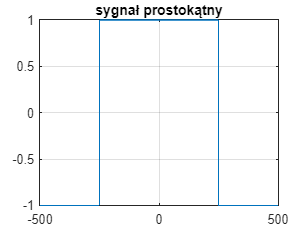

syms t t1 t2 offset x
T0 = 1000;
f0 = 1/T0;
w0 = 2*pi*f0;
t1 = -T0/2;
t2 = t1 + T0;
offset = 0;
BND = [t1,t2] + offset;
y = 2*(rectangularPulse(t1/2,t2/2,t)-0.5);
figure
fplot(y,BND)
grid on
title('sygnał prostokątny')

Współczynniki zespolone szeregu Fouriera

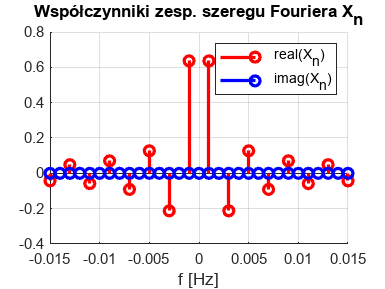

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
 Xn = (1/T0)*int(y*exp(-1i*w0*n*t),t,BND);
 X(n+NT+1) = Xn;
end
figure; hold on
stem(ind*f0,real(X),'r','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'b','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

Współczynniki an, bn

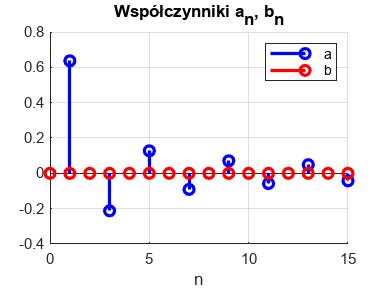

a=[];
b=[];
for n = 0:NT
 a(n+1) = (1/T0)*int(y*cos(w0*n*t),t,BND);
 b(n+1) = (1/T0)*int(y*sin(w0*n*t),t,BND);
end
figure; hold on, grid on
stem(0:NT,a,'b','LineWidth',2);
xlabel('n')
stem(0:NT,b,'r','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

Rekonstrukcja sygnału ciąłego na podstawie szeregu Fouriera

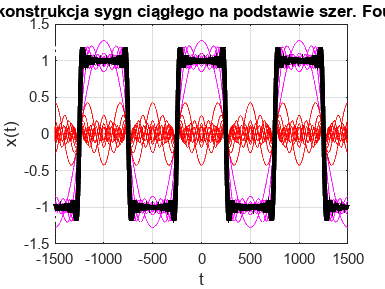

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);
figure;
plot(tt,xx,'m'); grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=1:NT
 xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
 xx = xx + xx_n;
 plot(tt,xx_n,'r');
 plot(tt,xx,'m');
 plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
 title(sprintf('n = %d',n+1));
 pause(0.5)
end
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

Rekonstrukcja sygnału

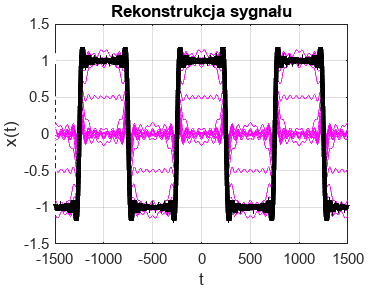

xx = zeros(1,length(tt));
figure(5);
plot(tt,xx,'m'); grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=-NT:NT
 xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
 xx = xx + xx_n;
 pause(0.5);
 plot(tt,real(xx),'m');
 plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end
plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off

Błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = x^{2}$$

pars_series = sum(abs(X).^2)

pars_series = 0.9747

pars_wave = subs(pars_wave, x, 1)

$$pars\_wave = 1$$

err_abs = double(abs(pars_wave - pars_series))

err_abs = 0.0253

err_rel = double(err_abs / pars_wave) * 100

err_rel = 2.5297

Wartość skuteczna

syms ev
ev = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
ev_d = double(ev);

ev = sqrt(int(x^2,t,BND)/T0)

$$ev = \sqrt{x^{2}}$$


ev_r = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

ev_r = 0.9873

THD

s = 0;
for n = 2:NT
 s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
 thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = 0

thd = 0.3333

thd = 0.3333

thd = 0.3887

thd = 0.3887

thd = 0.4141

thd = 0.4141

thd = 0.4288

thd = 0.4288

thd = 0.4383

thd = 0.4383

thd = 0.4450

thd = 0.4450

thd = 0.4500

### Sinus wyprostowany dwupołówkowo

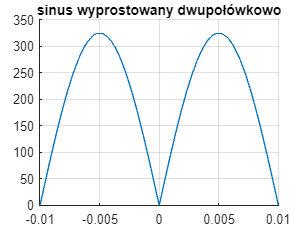

syms t t1 t2 offset x
T0 = 1/50;
f0 = 1/T0;
w0 = 2*pi*f0;
t1 = -T0/2;
t2 = t1 + T0;
offset = 0;
BND = [t1,t2] + offset;
z = abs(325*sin(50*2*pi*t));
figure
hold on
fplot(z, BND)
xlim(BND)
grid on
title("sinus wyprostowany dwupołówkowo")
hold off

Współczynniki zespolone szeregu Fouriera

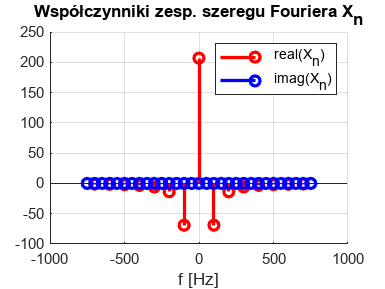

NT = 15;
X=[];
ind=-NT:NT;
for n = ind
 Xn = (1/T0)*int(z*exp(-1i*w0*n*t),t,BND);
 X(n+NT+1)=Xn;
end
figure; hold on
stem(ind*f0,real(X),'r','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'b','LineWidth',2);
grid on
legend('real(X_n)','imag(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')
hold off

Współczynniki an, bn

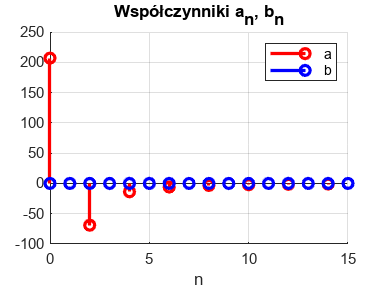

a=[];
b=[];
for n = 0:NT
 a(n+1) = (1/T0)*int(z*cos(w0*n*t),t,BND);
 b(n+1) = (1/T0)*int(z*sin(w0*n*t),t,BND);
end
figure; hold on, grid on
stem(0:NT,a,'r','LineWidth',2);
xlabel('n')
stem(0:NT,b,'b','LineWidth',2);
legend('a','b'),
title('Współczynniki a_n, b_n')
hold off

Rekonstrukcja sygn ciągłego na podstawie szeregu Fouriera

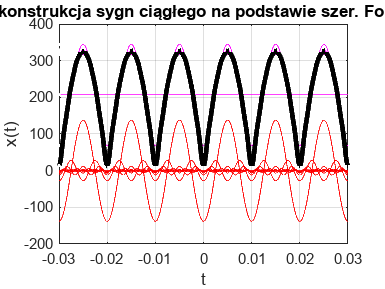

step = (BND(2)-BND(1))/1000;
tt = [BND(1)-T0 : step : BND(2)+T0];
xx = zeros(1,length(tt));
xx = xx + a(1);
figure;
plot(tt,xx,'m'); grid on, hold on;
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1], 'r'),
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=1:NT
 xx_n=2*(a(n+1)*cos(w0*n*tt)+b(n+1)*sin(w0*n*tt));
 xx = xx + xx_n;
 plot(tt,xx_n,'r');
 plot(tt,xx,'m');
 plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
 title(sprintf('n = %d',n+1));
 pause(0.5)
end
plot(tt,xx,'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(xx)-0.1,min(xx)+0.1],'w.')
title('Rekonstrukcja sygn ciągłego na podstawie szer. Fouriera')
hold off

Rekonstrukcja sygnału

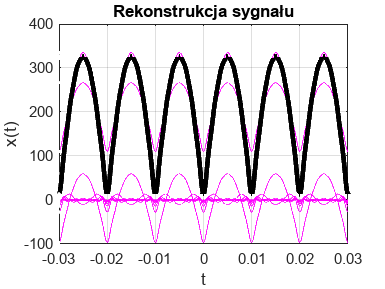

xx = zeros(1,length(tt));
figure(5);
plot(tt,xx,'m'); grid on, hold on;
pause(0.5)
xlabel('t'); ylabel('x(t)');
for n=-NT:NT
 xx_n=X(n+NT+1)*exp(1i*w0*n*tt);
 xx = xx + xx_n;
 pause(0.5);
 plot(tt,real(xx),'m');
 plot([tt(1),tt(2)],[max(real(xx))-0.1, min(real(xx))+0.1],'w.')
end
plot(tt,real(xx),'k','LineWidth',3); grid on, hold on
plot([tt(1),tt(2)],[max(real(xx))-0.1,min(real(xx))+0.1],'w.')
title('Rekonstrukcja sygnału')
hold off

Błąd aproksymacji

syms err
pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = x^{2}$$

pars_series = sum(abs(X).^2)

pars_series = 5.2808e+04

pars_wave = subs(pars_wave, x, 1)

$$pars\_wave = 1$$

err_abs = double(abs(pars_wave - pars_series))

err_abs = 5.2807e+04

err_rel = double(err_abs / pars_wave) * 100

err_rel = 5.2807e+06

Wartość skuteczna

syms skut
skut = sqrt(int(sin(t)^2,t,[0 2*pi])/(2*pi));
skd = double(skut)

skd = 0.7071

skut1 = sqrt(int(x^2,t,BND)/T0)

$$skut1 = \sqrt{x^{2}}$$

skut_xx = sqrt(trapz(real(xx(1001:2001)).^2)/1000)

skut_xx = 229.8005

THD

s = 0;
for n = 2:NT
 s = s + abs(a(n+1)+1j*b(n+1)).^2/2;
 thd = sqrt(s)/(abs(a(2)+1j*b(2))/sqrt(2))
end

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf

thd = Inf